#### PHYS 361, Winter 2024: Mid-Term

**Directions: **Please do your best to write code that addresses the following questions. You may be limited on time to complete every question, so I recommend browsing through them and starting with the questions you are most comfortable with first. You will receive partial credit for incorrect solutions, so do not let a "bug" or an error message cause you to take too long on a particular problem. Even if your code is not running correctly, try to write all of the elements of the code you understand. For example, you can still write a plot command even if you do not know how to import the data.

1. **[5 points] **Let x=[2,3,4,5,6] and y = [2,4,6,8,10]. Use them to calculate the following element-by-element expression the create a 5 element array w. 


$$w=x\;\ln \left(x^3 +y^2 \right)+\sqrt{\frac{y^3 }{{\left(x-y\right)}^2 }}$$


clear all;

% define variables
x = 2:6;
y = 2:2:10;

% calculate w
w = x .* log( (x.^3) + (y.^3) ) + sqrt( (y.^3) ./ ((x-y).^2) )

w =        Inf   21.5326   29.8876   39.8263   50.5256


2. **[5 points]  **Define $r=2.8\times10^4$and $s=16.8$, and, t=[1,2,3,4,5], x=[0,2,4,6,8], and y=[3,6,9,12,15]. Evaluate the following expression for R, again using element-by-element arithmatic to create a 5 element array.


$$R=\frac{r\left(-\textrm{xt}+{\textrm{yt}}^2 \right)}{15}-s^2 \left(y-0\ldotp 5x^2 \right)t$$


clear all;

% define variables
r = 2.8e4;
s = 16.8;
t = 1:5;
x = 0:2:8;
y = 3:3:15;

% calculate R
R = ( (r.*(-x.*t + y.*(t.^2)))./15 ) - (s.^2) .* (y - 0.5.*(x.^2)) .* t

R = 1.0e+05 *

    0.0475    0.3508    1.2795    3.2037    6.4932


3. **[5 points] **Solve the following system of linear equations for a, b, c, d, and e.


$$\begin{array}{l}
2\ldotp 5a-b+3c+1\ldotp 5d-e=57\ldotp 1\\
3a+4b-2c+2\ldotp 5d-e=27\ldotp 6\\
-4a+3b+c-6d+2e=-81\ldotp 2\\
2a+3b+c-2\ldotp 5d+4e=-22\ldotp 2\\
a+2b+5c-3d+4e=-12\ldotp 2
\end{array}$$


clear all;

% define system of equations in terms of Ax=b
A = [2.5, -1, 3, 1.5, -1; 3, 4, -2, 2.5, -1; -4, 3, 1, -6, 2; 2, 3, 1, -2.5, 4; 1, 2, 5, -3, 4];
b = [57.1; 27.6; -81.2; -22.2; -12.2];

% calculate x using \
x = A\b

x =    10.7409
   -2.6968
    4.9005
    3.1159
   -8.1755



% check solution manually
% (A*x) == b returns false, no clue why
A*x

ans =    57.1000
   27.6000
  -81.2000
  -22.2000
  -12.2000


4. A particle with a charge q a distance z above a disk with radius R and charge Q feels a force given by the following expression, 


$$F=\frac{\;\textrm{Qqz}}{2\epsilon_0 }\left(1-\frac{z}{\sqrt{\;z^2 +R^2 }}\right)$$


where $\epsilon_0 =8.85\times10^{-12}$ $C^2/(Nm^2)$ is the permitivity of free space. Let $q=2.5x10^{-5}$C , $Q=9.4\times10^{-6}$C, and $R=0.1$m. 

a) **[3 points] **Write the force equation as an anonymous function that depends on z.

b) **[2 points] **Use your function to evaluate the strength of the force at 1 m and `fprintf` to display the results to the command line.

b) **[3 points] **Use `fplot` to make a plot of F as a function of z for $0 \leq z \leq 0.8$ m.

clear all;

% define constants
% epsilon_0 [C^2 / (Nm^2)]
eps0 = 8.85e-12;

% define parameters
% charge [C]
q = 2.5e-5;
% charge [C]
Q = 9.4e-6;
% radius [m]
R = 0.1;

% a) define an annonymous function for force
F = @(z) ((Q.*q.*z) ./ (2 .* eps0)) .* (1 - z./sqrt(z.^2 + R.^2));

% b) calculate force at 1 meter
f_1m = F(1);
fprintf("The force at 1 meter is %f Newtons.", f_1m)

The force at 1 meter is 0.065890 Newtons.

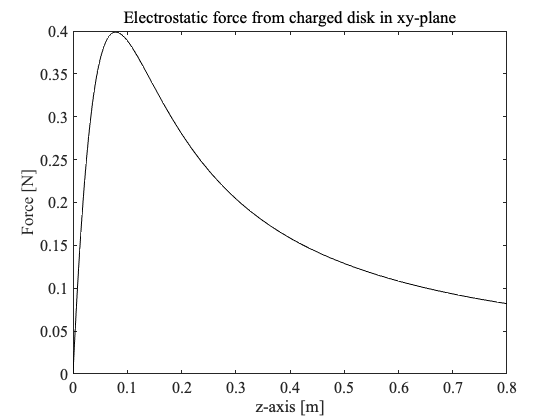


% c) plot force for z = [0, 0.8] [m];
plt = fplot(F, [0, 0.8], "-k");
plt.Parent.FontWeight = "normal";
plt.Parent.FontName = "Times New Roman";
plt.Parent.FontSize = 16;
xlabel("z-axis [m]")
ylabel("Force [N]")
title("Electrostatic force from charged disk in xy-plane", FontWeight="normal")

5. Plotting spectral data.

a) **[3 points] **Import data from the file called example_stellar_spectra.txt. Do this in your code, not using the built-in import button. 

b) **[3 points] **Plot the data. The Wavelength (in microns) should be on the horizontal axis and Flux (W/cm^2/micron) should be on the vertical axis. Adjust the limits of your plot so that it only shows the data between 0 and 3 microns.

c) **[2 points] **Include a line inside your code to save the figure as a png file.

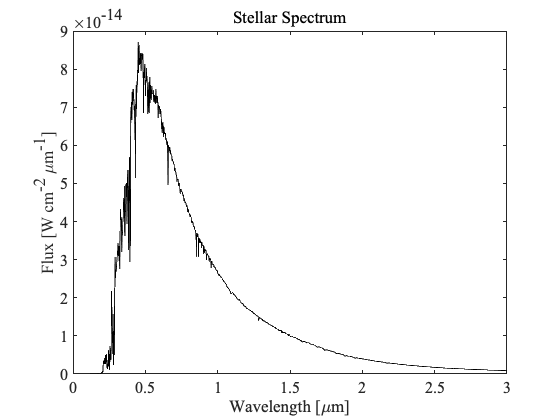

clear all;

% a) import spectral data
spectable = readtable("example_stellar_spectra.txt");

% b) plot data
plt = plot(spectable.Wavelength, spectable.Flux, "-k");
plt.Parent.FontWeight = "normal";
plt.Parent.FontName = "Times New Roman";
plt.Parent.FontSize = 16;
xlabel("Wavelength [\mum]")
ylabel("Flux [W cm^{-2} \mum^{-1}]")
title("Stellar Spectrum", FontWeight="normal")
xlim([0, 3])
exportgraphics(gcf, "stellar_spectrum.png")

6. **[8 points] **The Fibonacci numbers are a sequence of numbers where the first two number are 0 and 1 and each subsequent number is the sum of the previous two number in the series (e.g., 0,1,1,2,3,5,8,13,...).

Write a program that uses a loop to calculate the first 20 Fibonacci numbers and saves them in an array. *If you struggle with the logic of this problem, sketch out how you would calculate it by hand first and think about how to translate THAT into code.*

clear all;

% define list to store numbers with initial conditions
fib_nums = [0, 1];

% define number of numbers to calculate
N = 20;

% calculate fibnumbers up to N
% 0 is the 0th number, so N+1 gets the Nth number as the final entry
for i = 3:(N+1)
	fib_nums(i) = fib_nums(i-2) + fib_nums(i-1);
end


6.**[8 points] **You can calculate the Fibonacci constant $\Psi$ with the infinite sum:


$$\Psi=\sum_{n=1}^{\infty} \frac{1}{F_n}$$


where $F_n$ are the terms in the Fibonacci sequence. Write code that uses a while loop to calculate $\Psi$. You should stop your while loop when adding another term to the sum changes the value of $\Psi$ by less that $10^{-6}$, (i.e., $|\Psi_{n}-\Psi_{n-1}|<10^{-6}$).

clear all;

% define threshold to stop calculation
diff_thresh = 1e-6;

% define list of fibonacci numbers
fib_nums = [0, 1];

% initialize variables
% Psi for n=1
Psi = 1/1;
% difference of Psi and previous Psi
Psi_diff = 1;
% counter
n = 1;

% begin while loop until Psi_diff < diff_thresh
while Psi_diff >= diff_thresh
	% store previous Psi
	Psi_nm1 = Psi;

	% iterate counter
	n = n + 1;

	% calculate next fib_num
	% the fib_nums start at n=0 so we work with n+1 as 'current' value
	fib_nums(n+1) = fib_nums(n) + fib_nums(n-1);

	% calculate new Psi
	Psi = Psi + (1 / fib_nums(n+1));

	% calculate difference
	Psi_diff = abs(Psi - Psi_nm1);

	% over-iteration protection
	if n > 1000
		break;
	end
end

% print Fibonacci constant
fprintf("Fibonacci constant after %d terms: %f", n, Psi)

Fibonacci constant after 31 terms: 3.359884

**[5 points] **These points will be awarded (or partially awarded) based on the "style" af your code. Are you choosing appropriate variable names? Are you coding in an efficient way with a reasonable number of lines? Are you choosing the most effective coding structures to complete the task? Did you surpress all but the intended output?